# SNW_DS_MAIN Small Solution Analysis

This is the example vignette for function: [**snw_ds_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_ds_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for vfi and gets distribution induced by policy functions and exogenous distributions. Small Simulations. **Looped** to get distribution, but uses **bisect vec** for VFI.

## Test SNW_DS_MAIN Defaults Small

Call the function with testing defaults.

mp_params = snw_mp_param('default_small');
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = false;
mp_controls('bl_print_ds') = false;
mp_controls('bl_print_ds_verbose') = false;
[Phi_true,Phi_adj,A_agg,Y_inc_agg,it,mp_dsvfi_results] = snw_ds_main(mp_params, mp_controls);

Elapsed time is 0.169161 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_test
Elapsed time is 0.756494 seconds.
Completed SNW_DS_MAIN;SNW_MP_PARAM=;default_small;SNW_MP_CONTROL=;default_test


Phi_true = Phi_true/sum(Phi_true(:));

## Show Key Distributional Statistics

mp_cl_mt_xyz_of_s = mp_dsvfi_results('mp_cl_mt_xyz_of_s');
disp(mp_cl_mt_xyz_of_s('tb_outcomes'))

                       mean         sd       coefofvar      min         max       pYis0      pYls0      pYgr0      pYisMINY      pYisMAXY      p0_01        p0_1         p1          p5          p10         p20        p25        p30        p40         p50         p60         p70         p75         p80         p90        p95        p99       p99_9     p99_99     fl_cov_a_ss    fl_cor_a_ss    fl_cov_ap_ss    fl_cor_ap_ss    fl_cov

## Base Param Results Define Frames Base

Define the matrix dimensions names and dimension vector values. Probability mass matrixes, Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 22:5:97, 100];
agrid = mp_params('agrid')';
eta_H_grid = mp_params('eta_H_grid')';
eta_S_grid = mp_params('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Probability Mass Along Age Dimensions

Where are the mass at? Analyze mass given state space components.

% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Exogenous Permanent States Mass: Life Cycle, Edu and Marraige

Tabulate value and policies along savings and shocks:

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,5,4];
% Value Function
tb_prob_aem = ff_summ_nd_array("P(Age, EDU, MARRY))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, EDU, MARRY))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    marry    edu    sum_age_19    sum_age_22    sum_age_27    sum_age_32    sum_age_37    sum_age_42    sum_age_47    sum_age_52    sum_age_57    sum_age_62    sum_age_67    sum_age_72    sum_age_77    sum_age_82    sum_age_87    sum_age_92    sum_age_97    sum_age_100
    _____    _____    ___    __________    __________    __________    __________    __________    __________    __________    _____

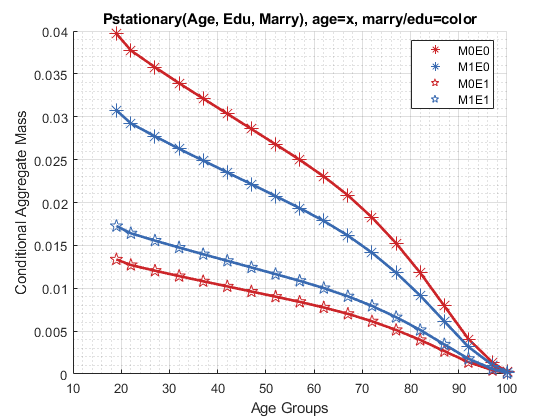

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Edu, Marry), age=x, marry/edu=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["M0E0", "M1E0", "M0E1", "M1E1"];
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
mp_support_graph('cl_scatter_shapes') = {'*', '*', 'p', 'p' };
mp_support_graph('cl_colors') = {'red', 'blue', 'red', 'blue'};
ff_graph_grid((tb_prob_aem{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

#### Kids and Marry By Age Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_prob_amarrykids = ff_summ_nd_array("P(Age, Kids, Marry))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, Kids, Marry))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    sum_age_19    sum_age_22    sum_age_27    sum_age_32    sum_age_37    sum_age_42    sum_age_47    sum_age_52    sum_age_57    sum_age_62    sum_age_67    sum_age_72    sum_age_77    sum_age_82    sum_age_87    sum_age_92    sum_age_97    sum_age_100
    _____    ____    _____    __________    __________    __________    __________    __________    __________    __________    __

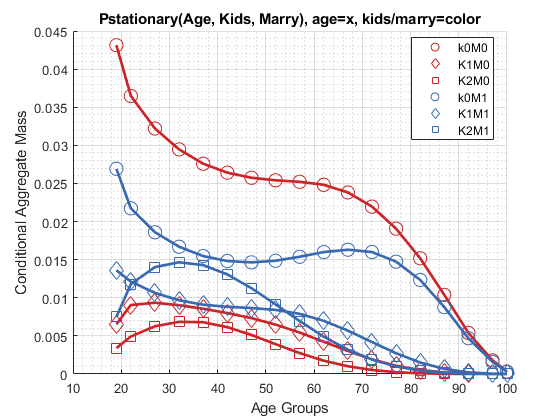

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Kids, Marry), age=x, kids/marry=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
ff_graph_grid((tb_prob_amarrykids{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Probability Mass Asset and Shock Dimensions

Where are the mass at?

% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Asset and Shock Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_prob_az = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings     sum_eta_1     sum_eta_2     sum_eta_3     sum_eta_4     sum_eta_5 
    _____    _________    __________    __________    __________    __________    __________

      1              0      0.050453       0.16674       0.18478      0.076365       0.01206
      2      0.0097656     0.0040908      0.016831      0.029635      0.023695     0.0019619
      3       0.078125     0.0044244      0.026464      0.041683      0.025501     0.0068678
      4        0.26367     0.0023268      0.023394      0.048735      0.033536     0.0074255
      5          0.625    0.00091361      0.011701      0.041638      0.037203     0.0087894
      6         1.2207    0.00024289     0.0039147      0.021434    

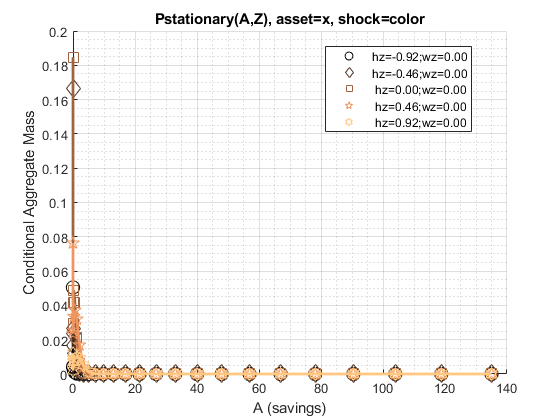

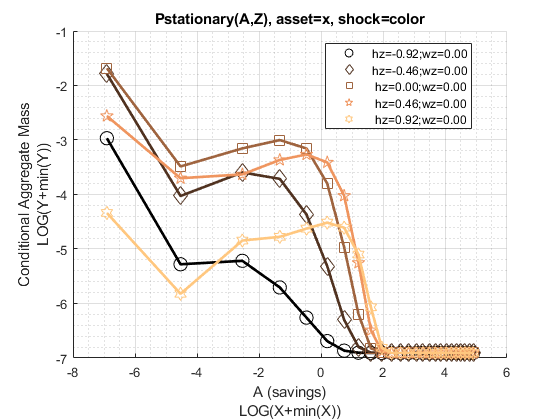

mp_support_graph('cl_st_graph_title') = {'Pstationary(A,Z), asset=x, shock=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.2f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_az{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);% Consumption Choices

#### Asset Mass by Age

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [3,4,5,6,1,2];
% Value Function
tb_prob_aage = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings     sum_age_19    sum_age_22    sum_age_27    sum_age_32    sum_age_37    sum_age_42    sum_age_47    sum_age_52    sum_age_57    sum_age_62    sum_age_67    sum_age_72    sum_age_77    sum_age_82    sum_age_87    sum_age_92    sum_age_97    sum_age_100
    _____    _________    __________    __________    __________    __________    __________    __________    __________    __________    __________    

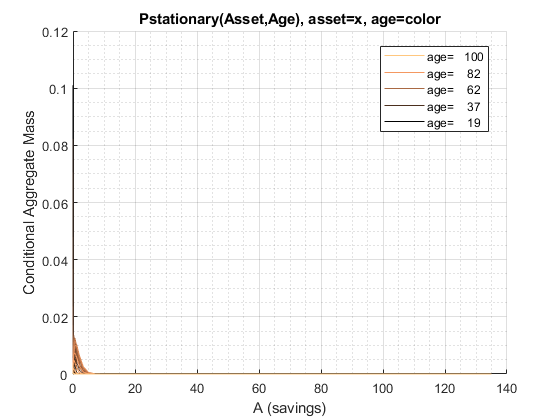

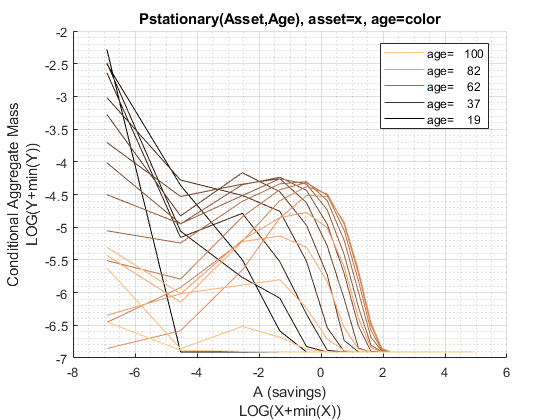

mp_support_graph('cl_st_graph_title') = {'Pstationary(Asset,Age), asset=x, age=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'age=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.0f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_aage{1:end, 3:end})', age_grid, agrid, mp_support_graph);% Consumption Choices

## Probability Statistics A, C and V Conditional on Ages

Where are the mass at?

ap_ss = mp_dsvfi_results('ap_ss');
c_ss = mp_dsvfi_results('cons_ss');
v_ss = mp_dsvfi_results('v_ss');
n_ss = mp_dsvfi_results('n_ss');

y_head_inc = mp_dsvfi_results('y_head_inc_ss');
y_spouse_inc = mp_dsvfi_results('y_spouse_inc_ss');

yshr_wage = mp_dsvfi_results('yshr_wage_ss');
yshr_SS = mp_dsvfi_results('yshr_SS_ss');
yshr_nttxss = mp_dsvfi_results('yshr_nttxss_ss');

for it_ctr=1:size(ap_ss, 1)
    if (ismember(it_ctr, round(linspace(1, size(ap_ss, 1), 3))))
        display(['age =' num2str(age_grid(it_ctr))]);
        
        % construct input data
        Phi_true_age = Phi_true(it_ctr, :, :, : ,: ,:);
        ap_ss_age = ap_ss(it_ctr, :, :, : ,: ,:);
        c_ss_age = c_ss(it_ctr, :, :, : ,: ,:);
        v_ss_age = v_ss(it_ctr, :, :, : ,: ,:);
        n_ss_age = n_ss(it_ctr, :, :, : ,: ,:);
        
        y_head_inc_age = y_head_inc(it_ctr, :, :, : ,: ,:);
        y_spouse_inc_age = y_spouse_inc(it_ctr, :, :, : ,: ,:);
        yshr_wage_age = yshr_wage(it_ctr, :, :, : ,: ,:);
        yshr_SS_age = yshr_SS(it_ctr, :, :, : ,: ,:);
        yshr_nttxss_age = yshr_nttxss(it_ctr, :, :, : ,: ,:);
        
        mp_cl_ar_xyz_of_s = containers.Map('KeyType','char', 'ValueType','any');
        mp_cl_ar_xyz_of_s('ap_ss') = {ap_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('c_ss') = {c_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('v_ss') = {v_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('n_ss') = {n_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('y_head_inc') = {y_head_inc_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('y_spouse') = {y_spouse_inc_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('yshr_wage') = {yshr_wage_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('yshr_SS') = {yshr_SS_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('yshr_nttxss') = {yshr_nttxss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('ar_st_y_name') = ["ap_ss", "c_ss", "v_ss", "n_ss",...
            "y_head_inc", "y_spouse", "yshr_wage", "yshr_SS", "yshr_nttxss"];
        
        % controls
        mp_support = containers.Map('KeyType','char', 'ValueType','any');
        mp_support('ar_fl_percentiles') = [0.01 10 25 50 75 90 99.99];
        mp_support('bl_display_final') = true;
        mp_support('bl_display_detail') = false;    
        mp_support('bl_display_drvm2outcomes') = false;  
        mp_support('bl_display_drvstats') = false;
        mp_support('bl_display_drvm2covcor') = false;
    
        % Call Function     
        mp_cl_mt_xyz_of_s = ff_simu_stats(Phi_true_age(:)/sum(Phi_true_age,'all'), mp_cl_ar_xyz_of_s, mp_support);
    end
end

age =19


xxx tb_outcomes: all stats xxx
    OriginalVariableNames        ap_ss          c_ss          v_ss          n_ss        y_head_inc      y_spouse      yshr_wage     yshr_SS    yshr_nttxss
    ______________________    ___________    __________    __________    ___________    ___________    ___________    __________    _______    ___________

    {'mean'              }      0.0047508       0.70715       -4.3931         1.8895        0.74346         0.1253             1        0         0.17165 
    {'sd'                }       0.018475       0.28644        3.5213        0.93753        0.34906        0.13589    2.2204e-16        0        0.021539 
    {'co

age =62


xxx tb_outcomes: all stats xxx
    OriginalVariableNames       ap_ss        c_ss         v_ss         n_ss       y_head_inc    y_spouse      yshr_wage     yshr_SS    yshr_nttxss
    ______________________    _________    _________    _________    _________    __________    _________    ___________    _______    ___________

    {'mean'              }      0.82038       1.1371      -1.9891       1.8923       1.4048       0.22995        0.92534        0          0.19774
    {'sd'                }      0.85976      0.51988       2.3079      0.94543      0.76251       0.24946        0.06993        0          0.02001
    {'coefofvar'         }        1.048 

age =100


xxx tb_outcomes: all stats xxx
    OriginalVariableNames     ap_ss      c_ss          v_ss          n_ss       y_head_inc      y_spouse     yshr_wage       yshr_SS      yshr_nttxss
    ______________________    _____    _________    __________    __________    ___________    __________    __________    ___________    ___________

    {'mean'              }       0       0.39835       -2.4687        1.4869         0.2593       0.20854       0.29733        0.70145      -0.56246 
    {'sd'                }       0       0.18159        1.0203       0.51938       0.022397       0.22193       0.31261        0.31156       0.33785 
    {'coefofvar'         }  